%Q1 
img = imread('ex3.jpg');   % lire l'image
figure;
imshow(img);   


%V={ v € H1, v=0 sur la frontière de Dirichlet}
% est l'espace de Hilbert utilisé pour écrire la formulation
% variationelle du problème.

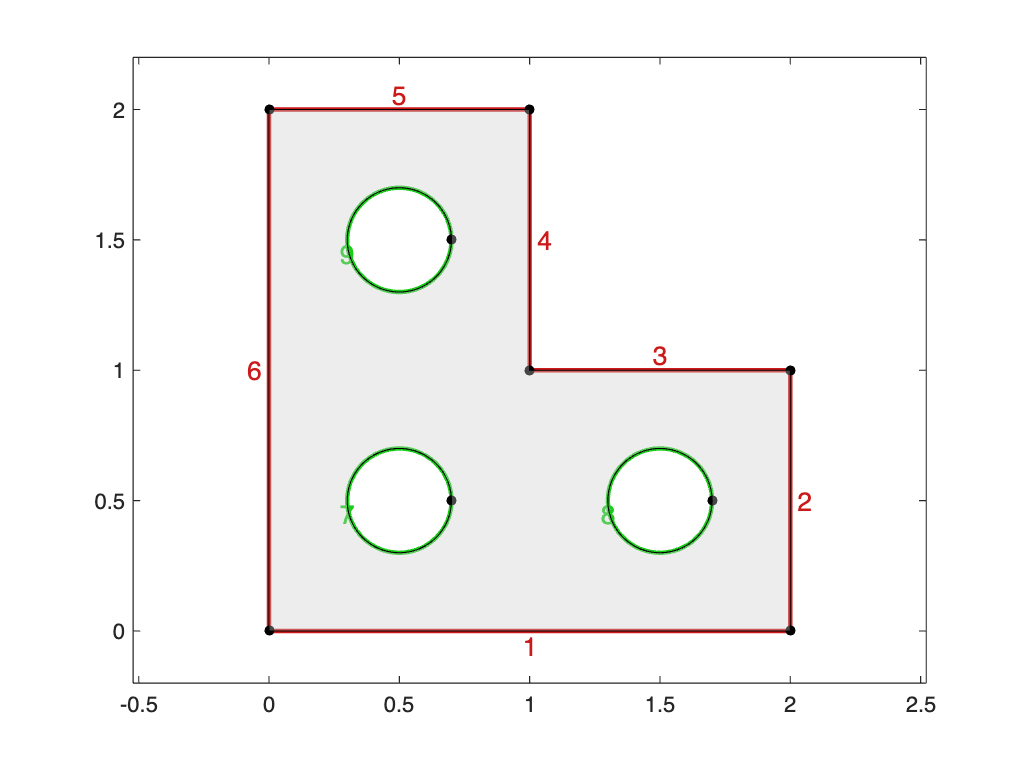

%Q2 Définition du maillage

nodes = [0 0 ; 2 0 ; 2 1 ; 1 1 ; 1 2 ; 0 2 ; .7 .5 ; 1.7 .5 ; .7 1.5];
edges = {{1 ,2} ,{2 ,3} ,{3 ,4} ,{4 ,5} ,{5 ,6} ,{6 ,1} ,...
{7 ,7 ,' 0.5+0.2* cos( t )',' 0.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'} ,...
{8 ,8 ,' 1.5+0.2* cos( t )',' 0.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'} ,...
{9 ,9 ,' 0.5+0.2* cos( t )',' 1.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'}};
domain = Domain( nodes , edges ) ;
domain.plot ('edgelabels') ;

h = 0.1;
mesh = Mesh( domain ,h , h/5) ;

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (5117 triangles, 0.4 s)


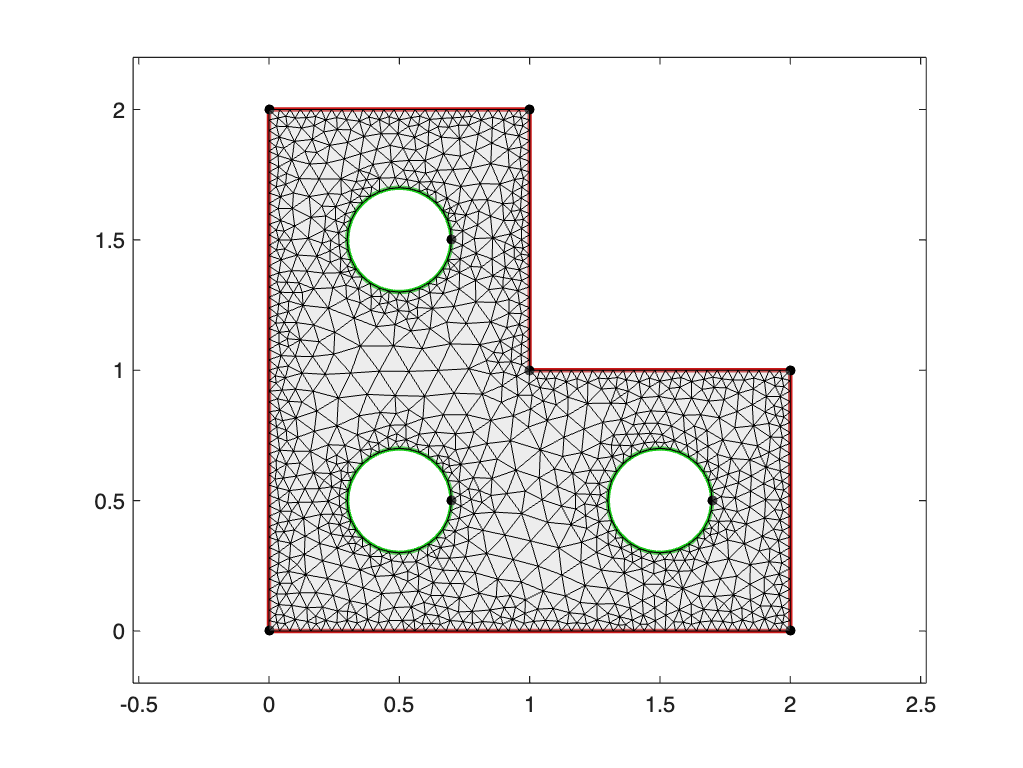

mesh.plot ;

%Q3
P=mesh.nodes;
E = mesh.boundary_edges(:,1:2);
B=matriceMbord(P,E);


%Q4 Pour résoudre (2), on utilise la formulation linéaire
P=mesh.nodes;
T=mesh.triangles;
K=matriceK(P,T);
I_neu=mesh.boundary(5);
I_dir=mesh.boundary(2);
Eneu = mesh.boundary_edges(I_neu,1:2);
Mneu=matriceMbord(P,Eneu);

%Condition de Neumann
G = P(:,1).*(P(:,1)-1);
Bneu=Mneu*G;

%Condition de Dirichlet
K(I_dir, :)= 0;
nI = length(I_dir);
K(I_dir, I_dir)= speye(nI);
B(I_dir)= 0;

%Résolution 
U=K \ B;

%Q5
dU=mesh.grad(U);   
ndU=norm(dU)^2;

figure;
mesh.image(dU);
hold on
mesh.quiver(dU);
title('igrad(u)');

figure;
mesh.image(ndU);
title('norme carrée de grad(u)');

